% vna_scpi.mlx
% Arba Shkreli, 02/16/2024
% Example taken and modified from 
% https://www.keysight.com/us/en/assets/9921-02561/programming-guides/FFProgrammingHelp.pdf#%5B%7B%22num%22%3A139%2C%22gen%22%3A0%7D%2C%7B%22name%22%3A%22XYZ%22%7D%2C70%2C143%2C0%5D
% on page 83 to get into data transfer from FieldFox N9923A on MATLAB

%%% CHANGES: `tcpip` interface is deprecated and must change to `tcpclient`

% Instantiate connection to Keysight FieldFox via LAN as Socket at Port 5025
% Alter the TCPIP address to match your targeted FieldFox IP address.
fieldFox = tcpclient('169.254.170.154',5025);

%Set input and output buffer default sizes
set(fieldFox, 'InputBufferSize', 8096);
set(fieldFox, 'OutputBufferSize', 8069);

% Default binary data read is BigEndian resulting in corrupt data.
% Modify return of binary data from default BigEndian to LittleEndian
% via MathWorks SET command
fieldFox.ByteOrder = "little-endian";

% 'Hello World' equivalent, i.e. Identification Query String
fprintf(fieldFox,'*IDN?\n');
myId = fscanf(fieldFox,'%c');
% Clear the status registers and all potential error 
% indications within the error queue prior to starting applications.
% Also, check the error queue via 'SYST:ERR?' error query and ensure 
% the error indication is '0, "No Error".
fprintf(fieldFox,'*CLS\n');
fprintf(fieldFox,'SYST:ERR?\n');
initErrCheck = fscanf(fieldFox,'%c');

% Set Instrument and various other important items
% Instrument mode to Network Analyzer
fprintf(fieldFox,'INST:SEL ''NA''');

% Trigger mode to continuous off
fprintf(fieldFox,'INIT:CONT 0\n');

% Set start and stop frequencies. 
fprintf(fieldFox,'FREQ:STAR 1E9;STOP 2E9\n');

% Set number of trace points
fprintf(fieldFox,'SWE:POIN 1601\n');

% Trace 1 to measurement of S21 and select that measurement as active
fprintf(fieldFox,'CALC:PAR1:DEF S21;SEL\n');

% Hold off for operation complete to ensure settings
fprintf(fieldFox,'*OPC?\n');
done = fscanf(fieldFox,'%1d');

% Trigger single sweep with hold off via *OPC? Operation Complete Query.
% For long sweeps times there may be a TCPIP hold off or time out setting
% that must be increased.
fprintf(fieldFox,'INIT;*OPC?\n');
trigComplete = fscanf(fieldFox,'%1d');

% Query FORMATTED data from fieldFox
% Set data format to real-32 bin block transfer
fprintf(fieldFox, 'FORM:DATA REAL,32\n');
fprintf(fieldFox,'CALC:DATA:FDATA?\n');
myBinData = binblockread(fieldFox,'float');

% There will be a line feed not read, i.e. hanging. Read it 
% to clear buffer. If you do not read the hanging line feed
% a -410, "Query Interrupted Error" will occur
hangLineFeed = fread(fieldFox,1);

% Query of x-axis stimulus
% Set data format to real-64 bin block transfer. Real 64 bit to ensure
% Hz resolution in GHz capable analyzers.
fprintf(fieldFox, 'FORM:DATA REAL,64\n');
fprintf(fieldFox,'SENS:FREQ:DATA?\n');
myBinStimulusData = binblockread(fieldFox,'double');

% There will be a line feed not read, i.e. hanging. 
% Read it to clear buffer.
hangLineFeed = fread(fieldFox,1);

% Within the MatLab GUI display data and stimulus numbers and plot same
display myBinData

myBinData


display myBinStimulusData

myBinStimulusData


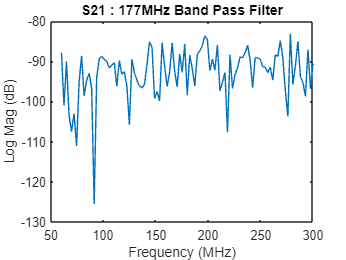


% MatLab plot related commands and efforts:
% Convert FieldFox returned frequency data to units of MHz
myStimulusDataMHz = myBinStimulusData/1E6;
clear title xlabel ylabel
plot(myStimulusDataMHz, myBinData)
title('S21 : 177MHz Band Pass Filter')
xlabel('Frequency (MHz)')
ylabel ('Log Mag (dB)')


% Check Error Queue. A "*CLS" was asserted at the beginning of the
% application. This will clear the entire error queue. Upon completion of
% the application the error queue is queried a final time. If the
% application is written correctly and there are no hardware failures the
% final error query check via 'SYST:ERR?' should return '0, "No Error" else
% the application is in error.
fprintf(fieldFox, 'SYST:ERR?')
finalErrCheck = fscanf(fieldFox, '%c')

finalErrCheck =     '0,"No error"
     '



%Close session to instrument prior to completion
clear fieldFox;